# Compare Denoised Signals

Denoise a signal in different ways and compare results.

Load a datafile that contains clean and noisy versions of a signal. Plot the signals.

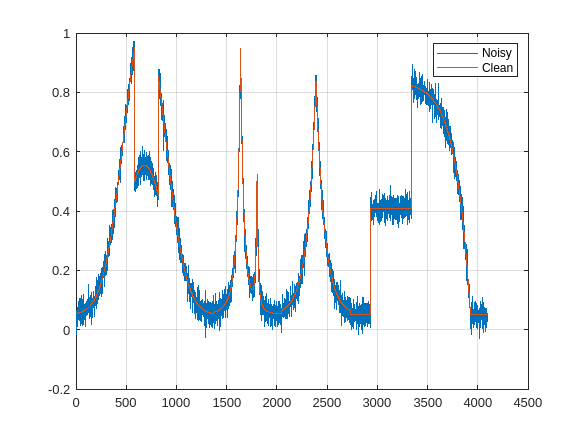

load fdata
plot(fNoisy)
hold on
plot(fClean)
grid on
legend("Noisy","Clean")
hold off

Denoise the signal using the `sym4` and `db1` wavelets, with a nine-level wavelet decomposition. Plot the results.

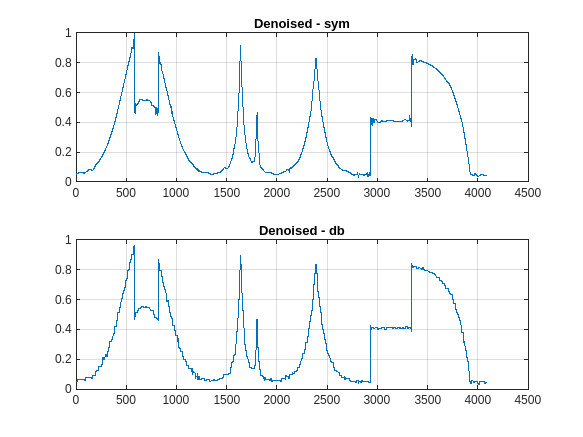

cleansym = wdenoise(fNoisy,9,Wavelet="sym4");
cleandb = wdenoise(fNoisy,9,Wavelet="db1");
figure
subplot(2,1,1)
plot(cleansym)
title("Denoised - sym")
grid on
subplot(2,1,2)
plot(cleandb)
title("Denoised - db")
grid on

Compute the SNR of each denoised signal. Confirm that using the `sym4` wavelet produces a better result.

snrsym = -20*log10(norm(abs(fClean-cleansym))/norm(fClean))

snrsym = 35.9623

snrdb = -20*log10(norm(abs(fClean-cleandb))/norm(fClean))

snrdb = 32.2672

Load in a file which contains noisy data of 100 time series. Every time series is a noisy version of `fClean`. Denoise the time series twice, estimating the noise variance differently in each case.

load fdataTS
cleanTSld = wdenoise(fdataTS,9,NoiseEstimate="LevelDependent");
cleanTSli = wdenoise(fdataTS,9,NoiseEstimate="LevelIndependent");

Compare one of the noisy time series with its two denoised versions.

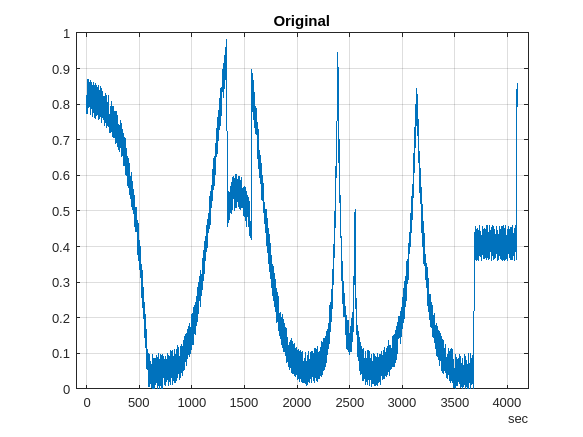

figure
plot(fdataTS.Time,fdataTS.fTS15)
title("Original")
grid on

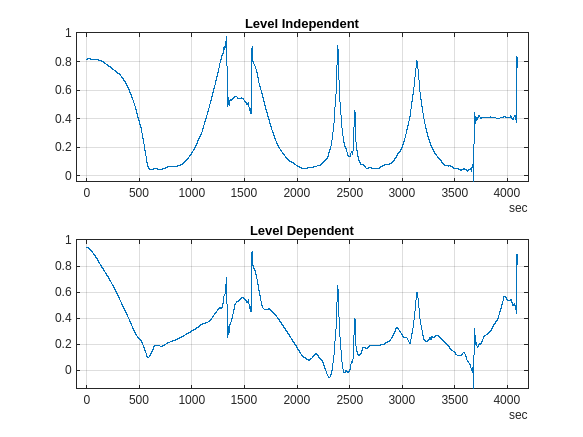

figure
subplot(2,1,1)
plot(cleanTSli.Time,cleanTSli.fTS15)
title("Level Independent")
grid on
subplot(2,1,2)
plot(cleanTSld.Time,cleanTSld.fTS15)
title("Level Dependent")
grid on

*Copyright 2012 The MathWorks, Inc.*